## Controlo Automático - Projecto

%% Inicialização do ambiente
clear ; close all; clc

% Importamos os dados dos pacientes
data = importdata('ROC_REAL_50.mat');

% Definimos uma seed estatica para o gerador de números aleatórios de forma
% a podermos repetir os experimentos com resultados determinísticos
rng(42);

### **Questão 1**

**a)** Selecionamos 10 pacientes da base de dados:

rndIDX = randperm(50);
sample_size = 10

sample_size = 10

sample = data(rndIDX(1:sample_size), :)

sample =     0.0219    1.2746
    0.0528    2.5362
    0.0352    1.5503
    0.0293    1.4728
    0.0308    1.9499
    0.0330    2.4823
    0.0282    1.2615
    0.0295    1.2390
    0.0329    2.5669
    0.0394    2.0425


t_size = 600

t_size = 600

**b) e c)**

Temos que $(s + \alpha )(s + 4\alpha )(s + 10\alpha ) = s^3 + 15\alpha s^2 + 54\alpha ^2 s + 40\alpha ^3$, o que nos dá os fatores $[1 \ 15a \ 54a^2 \ 40a^3]$.

Cálculo de $c_e \left(t\right)$ e da respectiva média.

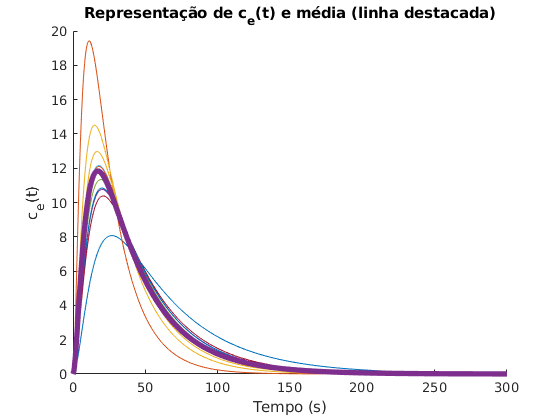

figure(1);
hold on
t = linspace(0, 300, t_size);
Ce = zeros(t_size, sample_size);
G = @(a) tf(40*a^3, [1 15*a 54*a^2 40*a^3]);
for idx = 1 : sample_size
    a = sample(idx, 1);
    Ce(:, idx) = impulse(G(a) * 600, t);
end
plot(t, Ce);
mean_ce = mean(Ce, 2);
plot(t, mean_ce, 'LineWidth', 4);
%fplot(@(x) 1489.2*x);
xlabel('Tempo (s)')
ylabel('c_{e}(t)')
title('Representação de c_{e}(t) e média (linha destacada)')
hold off

Cálculo de $R\left(t\right)$ e da respectiva média.

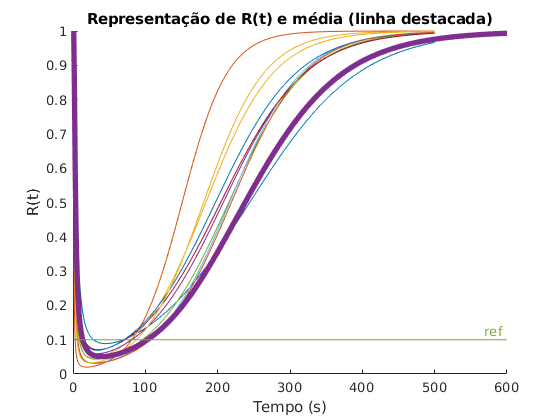

r0 = 1;
EC50 = 1;
figure(2);
hold on
t = linspace(0, 500, t_size);
% O transposto da segunda coluna de `sample` é repetido verticalmente
% `t_size` vezes e multiplicado elemento a elemento com `Ce`
Rt = @(Ce, gamma) r0 ./ (1 + (Ce / EC50) .* gamma);
R = Rt(Ce, repmat(sample(:, 2)', t_size, 1));
plot(t, R);
gamma = mean(R, 2);
plot(gamma, 'LineWidth', 4);
% Ver label.m
label(plot(ones(t_size, 1) * 0.1), 'ref', 'location', 'right');
xlabel('Tempo (s)')
ylabel('R(t)')
title('Representação de R(t) e média (linha destacada)')
hold off

### **Questão 2**

**a)**

Pela condição de estabilidade necessária do critério de estabilidade de Routh-Hurwitz, fácilmente vemos que $\alpha$ tem que ser não negativo, caso contrário pelo menos um dos coeficientes do polinómio do denominador seria negativo. 

Aplicando o método de Routh-Hurwitz obtemos a seguinte tabela:

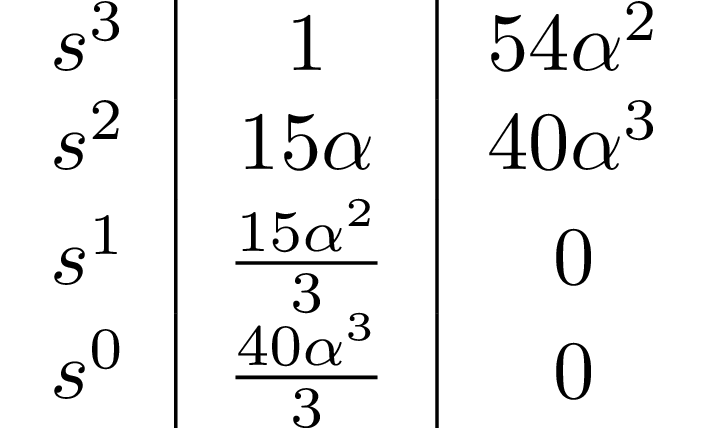

Daqui, fácilmente vemos que os valores da primeira coluna têm todos o mesmo sinal, se $15\alpha > 0$, $\frac{154\alpha^2}{3} > 0$ e $\frac{40\alpha^3}{3} > 0$, o que acontece para todos os $\alpha > 0$, ou seja, para todos os valores estritamente positivos de $\alpha$, o sistema é estável.

**b)**

figure(3);
hold on;
alpha = mean(sample(:, 1))

alpha_mean = 0.0333

sys = G(alpha) * 6;
constant_infusion = step(sys);
step_info = stepinfo(constant_infusion)

step_info = struct with fields:
        RiseTime: 100.8415
    SettlingTime: 186.5193
     SettlingMin: 5.3991
     SettlingMax: 5.9958
       Overshoot: 0
      Undershoot: 0
            Peak: 5.9958
        PeakTime: 334


plot(constant_infusion);
xlabel('Tempo (s)');
ylabel('c_{e}(t)');
title('Resposta de c_{e}(t) à infusão constante de rocurónio');

**c)**

[Z, gain] = zero(sys);
gain

gain = 0.0089

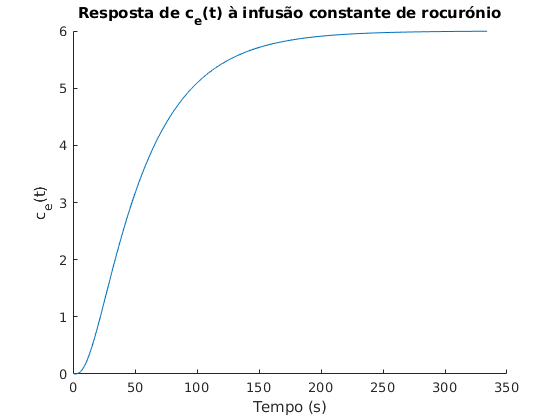

hold off;

**d)**

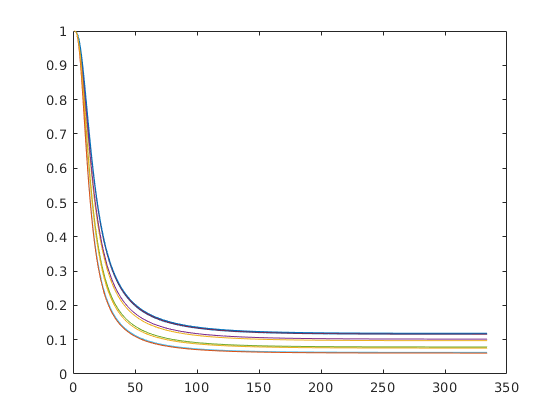

figure(4);
plot(Rt(constant_infusion, repmat(sample(:, 2)', length(constant_infusion), 1)));

**e)**

Os polos são $-\alpha$ e $-4\alpha$.


$$40*a^3/((s + a)*(s + 4*a)) = 40 * a ^ 3 / (s^2 + 5*a*s + 4*a^2)$$


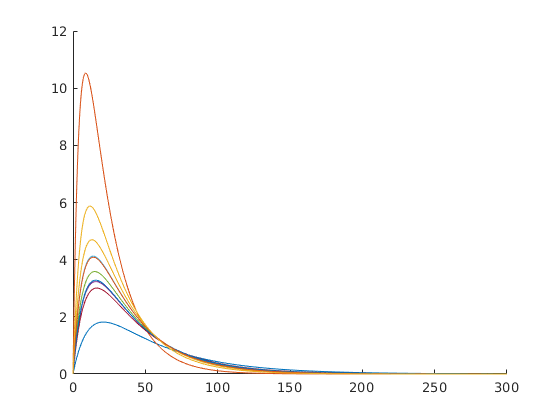

figure(5);
hold on;
H = @(a) tf(40*a^3, [1 5*a 4*a^2]);
t = linspace(0, 300, t_size);
Ce_h = zeros(t_size, sample_size);
for idx = 1 : sample_size
    a = sample(idx, 1);
    Ce_h(:, idx) = impulse(H(a) * 600, t);
end
plot(t, Ce_h);
hold off;

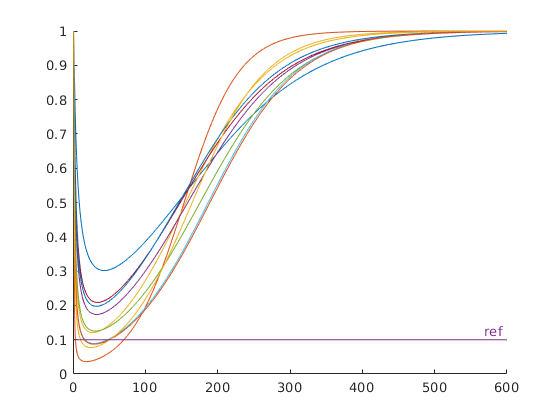

figure(6);
hold on;
plot(Rt(Ce_h, repmat(sample(:, 2)', t_size, 1)));
label(plot(ones(t_size, 1) * 0.1), 'ref', 'location', 'right');
hold off;

**f)**

Como podemos observar pelos dois gráficos apresentados em cima, estes têm comportamentos semelhantes aos correspondentes à função de transferência exata, exceto que apresentam uma magnitude diferente. Verificamos que com esta aproximação, o modelo não tem o desempenho pretendido já que muito poucos pacientes atingem o nível de NBM de referência com a administração do bólus inicial.

### **Questão 3**

**a)**

Obtenção do modelo (A,B,C,D) para o sistema input/output através da Função de Transferência.


$$G(s)=\frac{40\;\alpha {\;}^3 }{s^3 +15\;\alpha \;s^2 +50{\;\alpha }^2 \;s+40{\;\alpha }^3 }$$
 
$$\iff$$



$$\frac{Y\left(s\right)}{U\left(s\right)}=\frac{40\;\alpha {\;}^3 }{s^3 +15\;\alpha \;s^2 +50{\;\alpha }^2 \;s+40{\;\alpha }^3 }$$
 
$$\iff$$



$$Y\left(s\right)\cdot \left(s^3 +15\;\alpha \;s^2 +50{\;\alpha }^2 \;s+40\;\alpha {\;}^3 \right)=40\;\alpha \;U\left(t\right)$$


No domínio do tempo, pela $\mathcal{L}^{-1}$: $\dddot{y}(t)+15\alpha\ddot{y}+50\alpha^{2}\dot{y}(t)+40\alpha^{3}y(t)=40\alpha u(t)$

Ora, temos que:


$$y\left(t\right)=y\;=x_1$$



$$\dot{y} \left(t\right)=x_2 ={\dot{\;x} }_1$$



$$\ddot{\;y} \left(t\right)=x_3 ={\dot{\;x} }_2$$



$$\dddot{y}(t)=\dot{x_{3}}$$



$$u\left(t\right)=u$$


Portanto,


$$\begin{array}{l}
\dot{x_3 } +15\;\alpha {\;x}_3 +50\;\alpha^2 {\;x}_2 +4{0\;\alpha }^3 {\;x}_1 =40\;\alpha^3 \;u\iff \\
\dot{x_3 } =-40{\;\alpha }^3 \;x_1 -50\;\alpha^2 \;x_2 -15\;\alpha {\;x}_3 +40{\;\alpha }^3 \;u
\end{array}$$


Chegamos assim ao seguinte modelo de espaço de estados na forma canonica controlável em representação matricial:


$$\dot{x} =\overset{A}{\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-40\alpha {\;}^3  & -50\alpha^2  & -15\alpha 
\end{array}\right\rbrack } x+\overset{B}{\left\lbrack \begin{array}{c}
0\\
0\\
40\alpha^3 
\end{array}\right\rbrack } u$$



$$y=
[ \begin{array}{ccc}
1\limits^{x_{1}} &
0\limits^{x_{2}} &
0\limits^{x_{3}}
\end{array}\limits_{C}]x
+
\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack\limits_{D}
u$$


**b)**

alpha = mean(sample(:, 1));
%[num, den] = tfdata(G(alpha), 'v');
%[A, B, C, D] = tf2ss(num, den)
A = [0 1 0; 0 0 1; -40*alpha^3 -50*alpha^2 -15*alpha];
B = [0 0 40*alpha^3]';
C = [1 0 0];
D = [0];
G_ss = ss(A, B, C, D)

G_ss =
 
  A = 
              x1         x2         x3
   x1          0          1          0
   x2          0          0          1
   x3  -0.001477   -0.05545    -0.4995
 
  B = 
             u1
   x1         0
   x2         0
   x3  0.001477
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




Co = ctrb(G_ss)

Co =          0         0    0.0015
         0    0.0015   -0.0007
    0.0015   -0.0007    0.0003


Número de estados não controláveis:

unco = length(A) - rank(Co)

unco = 0

Concluímos assim, pelo teste de Kalman, que o sistema é controlável.

Por meio do MATLAB, conseguimos também testar a estabilidade do sistema da seguinte forma:

B = isstable(G_ss)

B = logical
   1


Sendo este um sistema de tempo contínuo, deduzimos que todos os polos se localizam na metade esquerda aberta do plano complexo.

**c)**

alpha = mean(sample(:, 1));
gamma = mean(sample(:, 2))

gamma = 1.8376

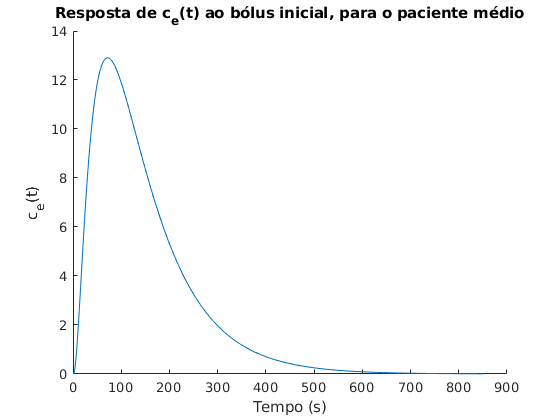


figure(7);
ce = impulse(G_ss*600);
plot(ce);
xlabel('Tempo (s)');
ylabel('c_{e}(t)');
title('Resposta de c_{e}(t) ao bólus inicial, para o paciente médio');

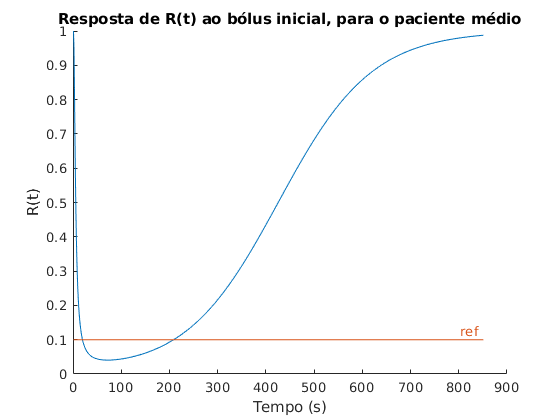


figure(8);
hold on;
plot(Rt(ce, gamma));
xlabel('Tempo (s)');
ylabel('R(t)');
title('Resposta de R(t) ao bólus inicial, para o paciente médio');
label(plot(ones(length(ce), 1) * 0.1), 'ref', 'location', 'right');
hold off;

### **Questão 4**

**a)**

Pela análise do gráfico de $R(t)$ apresentado em 3.c, uma escolha apropriada de $T$ é $150s$, já que este é um ponto no qual o efeito o bólus inicial está a diminuir tal que o níivel de NBM se aproxima do valor de referência.

figure(9);
T = 150;
%t = linspace(T, length(ce));
step(tf(ce))

%step(ce, t);